# Analysis of closed-loop offset and poles

Consider a closed-loop block diagram such as that below. We are specfically interested in how to use MATLAB to explore the offset, that is the asympotic error between the target r and output y for a constant r (use r=1 for convenience so offset is in effect a percentage). We also want to inestigate the closed-loop poles.

We assume users are familiar with the basic analysis tools such as covered in ***plotting_with_matlab.mlx, *** ***transferfunctions_and_poles.mlx ***and ***step_responses_with_matlab.mlx.***

This live script needs the control toolbox.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical and mathematical background

- Example 1

- Example 2

- Example 3

## 1. Technical and mathematical background

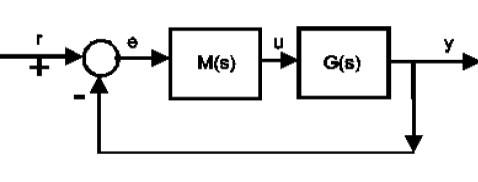

Using a standard feedback loop we have that both the offset  and poles can be computed with:

$E\left(s\right)=G_{\textrm{ce}} \left(s\right)R\left(s\right)$ with   $G_{\textrm{ce}} =\frac{1}{1+\textrm{GM}}$ and ${\textrm{offset}\;=\lim }_{s\longrightarrow 0} \frac{1}{1+G\left(s\right)M\left(s\right)}$

The poles are the roots of the denominator and the steady-state offset comes from $G_{\textrm{ce}} \left(0\right)$. The core MATLAB commands to analyse these characteristics are:

- ***pzmap.m*** for poles and zeros

- ***bode.m*** or system coefficients for extracting steady-state gains and/or offsets.

REMARKS: 

- If either *G(s)* or *M(s)* contain an integrator, the offset is zero (e.g. example 3). The code below does not check for that explicitly. In practice users could add this extra check first.

- Offset is only meaningfully defined if the closed-loop is stable, so this should also be checked first.

## 2. Example 1

Consider a system and compensator given as:

$G\left(s\right)=\frac{0\ldotp 2}{s^2 +s+0\ldotp 5};\;\;M\left(s\right)=10$;

Create these objects in MATLAB as follows

disp('SECTION 1 examples below here')

SECTION 1 examples below here


G=tf(0.2,[1 1 0.5])

G =
 
       0.6
  -------------
  s^2 + s + 0.5
 
Continuous-time transfer function.
Model Properties


M=10

M = 10

Next form the closed-loop transfer function $G_{\textrm{ce}} =\frac{1}{1+\textrm{GM}}$ and from that find the closed-loop poles (line 5) and steady-state offset (line 6: we **multiply by 100 to present  this as percentage**).

Gce=feedback(1,G*M)

Gce =
 
  s^2 + s + 0.5
  -------------
  s^2 + s + 6.5
 
Continuous-time transfer function.
Model Properties


closedlooppoles=pzmap(Gce)

closedlooppoles =   -0.5000 + 2.5000i
  -0.5000 - 2.5000i


offset_in_percentage = dcgain(Gce)*100   %% in percentage

offset_in_percentage = 7.6923

[ne,de]=tfdata(Gce,'v'); 
offset_from_coefficients = 100*ne(end)/de(end)   %% do not use if de(end)=0

offset_from_coefficients = 7.6923



disp('END OF SECTION 2')

END OF SECTION 2


Explore how the poles and offset change as you change the choice of M in line 3. You can do this by using the run section command. Remember **if any poles are in the RHP**, you have a divergent output so the offset computation is meaningless.

## 3. Example 2

From a MATLAB perspective there is nothing new in example 2, just a different example for you to explore. For this case it is interesting to explore what happens to the offset if M is too big and why? Again a reminder to check stability if you change the example given here.

$G\left(s\right)=\frac{5\left(s+4\right)}{s^4 +5+10s^2 +10s+4};\;\;M\left(s\right)=0\ldotp 2$;   

Create these objects in MATLAB as follows

disp('SECTION 3 examples below here')

SECTION 3 examples below here


G=tf(5*[1 4],[1 5 10 10 4])

G =
 
             5 s + 20
  -------------------------------
  s^4 + 5 s^3 + 10 s^2 + 10 s + 4
 
Continuous-time transfer function.



M=0.2

M = 0.2000

Using same relationships as in example 1:       $G_{\textrm{ce}} =\frac{1}{1+\textrm{GM}}$

Gce=feedback(1,G*M)

Gce =
 
  s^4 + 5 s^3 + 10 s^2 + 10 s + 4
  -------------------------------
  s^4 + 5 s^3 + 10 s^2 + 11 s + 8
 
Continuous-time transfer function.



closedlooppoles=pzmap(Gce)

closedlooppoles =   -2.0743 + 0.7065i
  -2.0743 - 0.7065i
  -0.4257 + 1.2185i
  -0.4257 - 1.2185i


offset_in_percentage = dcgain(Gce)*100

offset_in_percentage = 50


disp('END OF SECTION 3')

END OF SECTION 3


## 4. Example 3

From a MATLAB perspective there is nothing new in example 3, just a different example for you to explore. You may notice however that in this case the compensator is PI, that is, includes an integrator.

$G\left(s\right)=\frac{4}{s+2};\;\;M\left(s\right)=\frac{3s+2}{s}$;

Create these objects in MATLAB as follows

disp('SECTION 4 examples below here')

SECTION 4 examples below here


G=tf(4,[1  2])

G =
 
    4
  -----
  s + 2
 
Continuous-time transfer function.



M= tf([3 2],[1 0])

M =
 
  3 s + 2
  -------
     s
 
Continuous-time transfer function.



Using same relationships as in example 1:   $G_{\textrm{ce}} =\frac{1}{1+\textrm{GM}}$

Gce=feedback(1,G*M)

Gce =
 
    s^2 + 2 s
  --------------
  s^2 + 14 s + 8
 
Continuous-time transfer function.



closedlooppoles=pzmap(Gce)

closedlooppoles =   -13.4031
   -0.5969


offset_in_percentage = dcgain(Gce)*100

offset_in_percentage = 0


disp('END OF SECTION 4')

END OF SECTION 4
